# Problema 2

function plotPolinoameFundamentale(x_nodes)
 
    n = length(x_nodes) - 1; %gradul polinomului
    x_plot = linspace(min(x_nodes), max(x_nodes), 500);
    L_values = zeros(n+1, length(x_plot));
    
    % calculam fiecare polinom fundamental pentru fiecare x
    for k = 1:n+1
        for j = 1:length(x_plot)
            x = x_plot(j);
            produs = 1;
            for i = 1:n+1
                if i ~= k
                    produs = produs * (x - x_nodes(i)) / (x_nodes(k) - x_nodes(i));
                end
            end
            L_values(k, j) = produs;
        end
    end

    
    % Reprezentare grafica
    figure;
    hold on;
    for k = 1:n+1
        % Plotează curba ℓ_k(x)
        plot(x_plot, L_values(k, :), 'LineWidth', 2);
        
        % Află unde în x_plot se află cel mai apropiat punct de x_nodes(k)
        [~, idx] = min(abs(x_plot - x_nodes(k)));
        
        % Extrage valoarea ℓ_k în acel punct
        y_val = L_values(k, idx);
        
        % Plasează markerul exact pe curba ℓ_k în punctul său maxim
        plot(x_nodes(k), y_val, 'ko', 'MarkerFaceColor', 'k');
    end
    grid on;
    hold off;
end

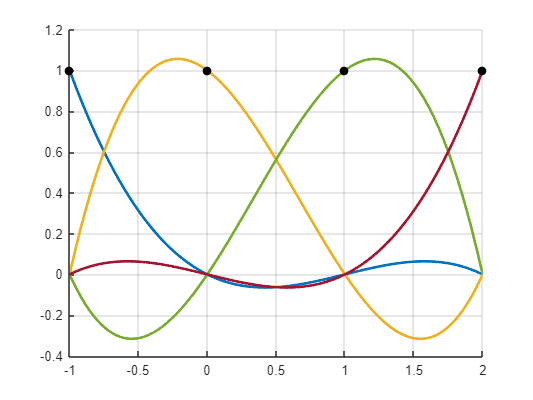

x_nodes = [-1, 0, 1, 2];
plotPolinoameFundamentale(x_nodes);